# Feedforward neural network

## Architecture

Feedforward

NNgenerator_args = struct();
NNgenerator_args.Ninputs = Ninputs;
NNgenerator_args.Noutputs = Noutputs;
NNgenerator_args.NFFlayers = 1;
NNgenerator_args.NRlayers = 0;
NNgenerator_args.NFFneurons = 2*Ninputs;
NNgenerator_args.Nwindow = 1;
NNgenerator_args.hidden_activation = 'reluLayer';
NNgenerator_args.output_activation = 'tanhLayer';
NNgenerator_args.dropout = 0;
NNgenerator_args.WinitFcn = 'narrow-normal';
NNgenerator_args.BinitFcn = 'narrow-normal';
NNgenerator_args.train_bias = false;
NNgenerator_args.scale_data = false;
NNgenerator_args.Xmax = Xmax;
NNgenerator_args.Ymax = Ymax

NNgenerator_args = struct with fields:
              Ninputs: 27
             Noutputs: 5
            NFFlayers: 1
             NRlayers: 0
           NFFneurons: 54
              Nwindow: 1
    hidden_activation: 'reluLayer'
    output_activation: 'tanhLayer'
              dropout: 0
             WinitFcn: 'narrow-normal'
             BinitFcn: 'narrow-normal'
           train_bias: 0
           scale_data: 0
                 Xmax: [27×1 double]
                 Ymax: [5×1 double]


FFnet = NNgenerator(NNgenerator_args);
FFnet = dlupdate(@double, FFnet);

LQR style

LQRLayers = [featureInputLayer(Ninputs, 'Name', 'LQRin')
             fullyConnectedLayer(Ninputs, 'WeightsInitializer', 'narrow-normal')
             batchNormalizationLayer
             tanhLayer
             fullyConnectedLayer(Ninputs, 'WeightsInitializer', 'narrow-normal')
             batchNormalizationLayer
             tanhLayer
             multiplicationLayer(2, 'Name', 'multiplicationLayer')
             fullyConnectedLayer(Noutputs, 'WeightsInitializer', 'narrow-normal')
             tanhLayer
             ];

% Crear el grafo de la red
LQRNet = dlnetwork;
LQRNet = addLayers(LQRNet, LQRLayers);
LQRNet = connectLayers(LQRNet, 'LQRin', 'multiplicationLayer/in2');
LQRNet = dlupdate(@double, LQRNet);

% FFnet = LQRNet

## Training

NNtrain_args = struct();
NNtrain_args.net = FFnet;
NNtrain_args.X_train = dlX_tr;
NNtrain_args.Y_train = dlY_tr;
NNtrain_args.X_val = dlX_val;
NNtrain_args.Y_val = dlY_val;
NNtrain_args.regularization = 0;
NNtrain_args.lr_i = 1e-2;
NNtrain_args.lr_f = 1e-6;
NNtrain_args.plots = 'training-progress'

NNtrain_args = struct with fields:
               net: [1×1 dlnetwork]
           X_train: [27×800 dlarray]
           Y_train: [5×800 dlarray]
             X_val: [27×200 dlarray]
             Y_val: [5×200 dlarray]
    regularization: 0
              lr_i: 0.0100
              lr_f: 1.0000e-06
             plots: 'training-progress'

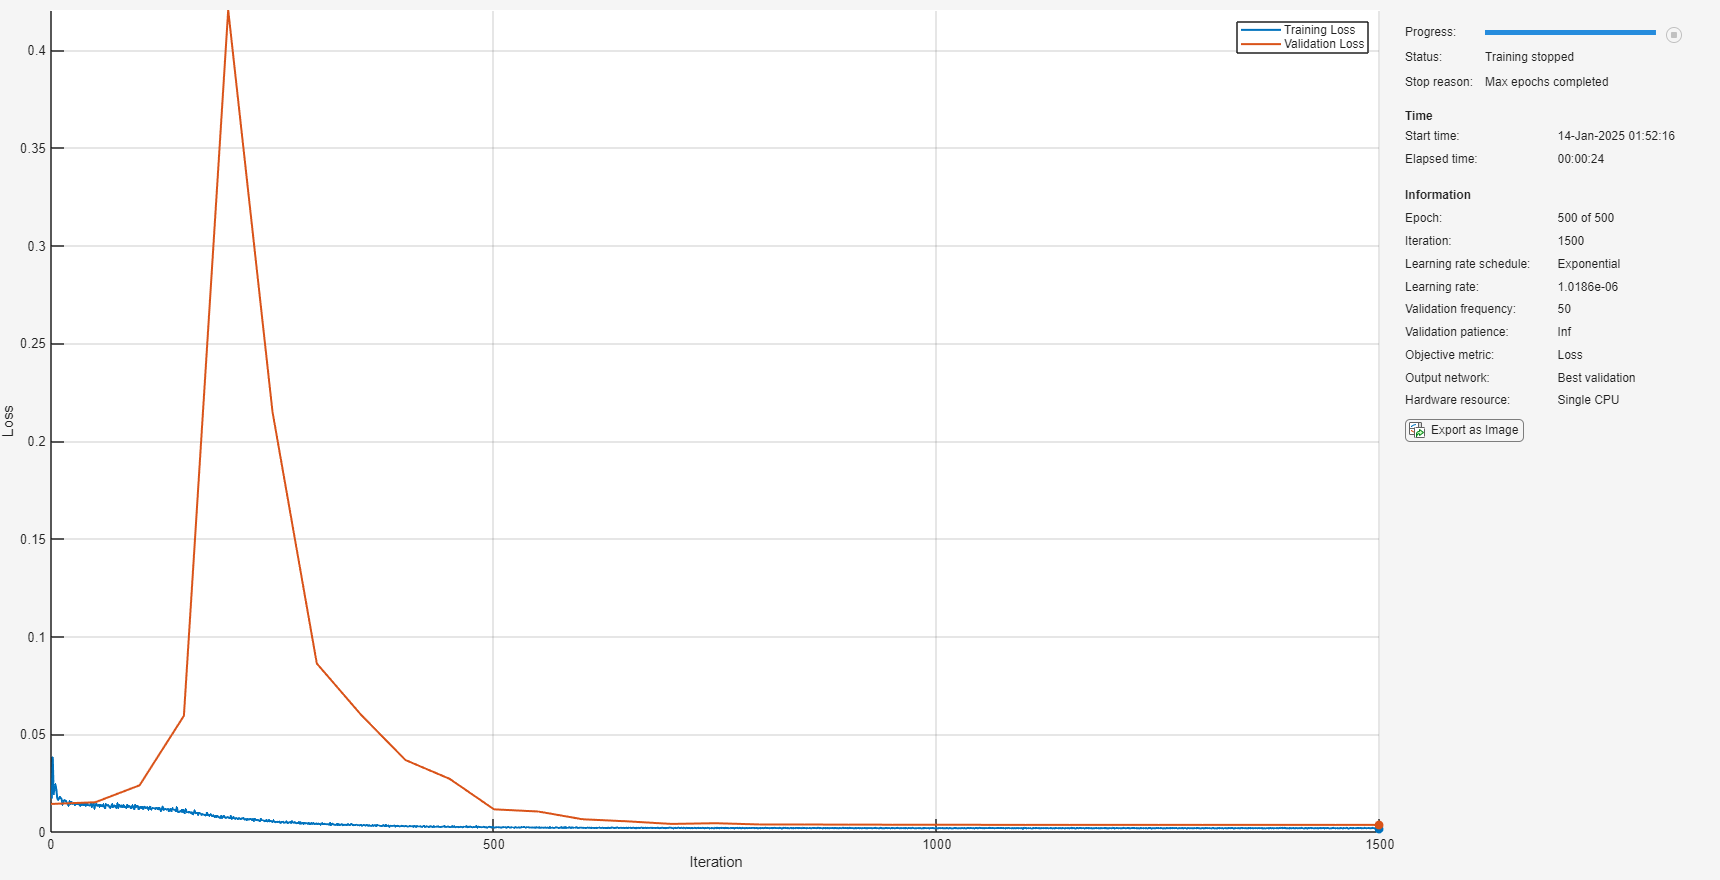

FFnet =   dlnetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
    Connections: [6×2 table]
     Learnables: [6×3 table]
          State: [2×3 table]
     InputNames: {'input'}
    OutputNames: {'tanhLayer'}
    Initialized: 1
  View summary with summary.


FFnet = NNtrain(NNtrain_args)

save('NeuralNetwork\Imitation\ActualArchitectures\FFnet.mat', "FFnet")

## Summary

dlY_tr_pred = FFnet.predict(dlX_tr);
dlY_val_pred = FFnet.predict(dlX_val);

Y_tr_pred = extractdata(dlY_tr_pred);
Y_val_pred = extractdata(dlY_val_pred);

trainPerformance = mse(dlY_tr_pred, dlY_tr);
valPerformance = mse(dlY_val_pred, dlY_val);

disp(['Rendimiento en el conjunto de entrenamiento: ', num2str(trainPerformance)]);

Rendimiento en el conjunto de entrenamiento: 0.0045994


disp(['Rendimiento en el conjunto de validación: ', num2str(valPerformance)]);

Rendimiento en el conjunto de validación: 0.0090978


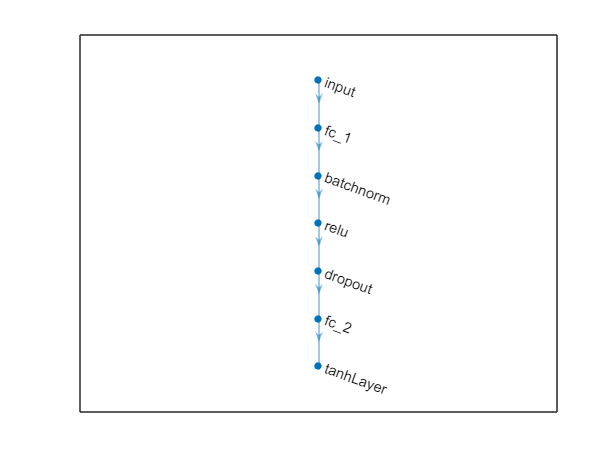


plot(FFnet)

analyzeNetwork(FFnet);
summary(FFnet)

   Initialized: true
   Number of learnables: 1.8k
   Inputs:
      1   'input'   27 features


# Performance analysis

## Complete timeseries

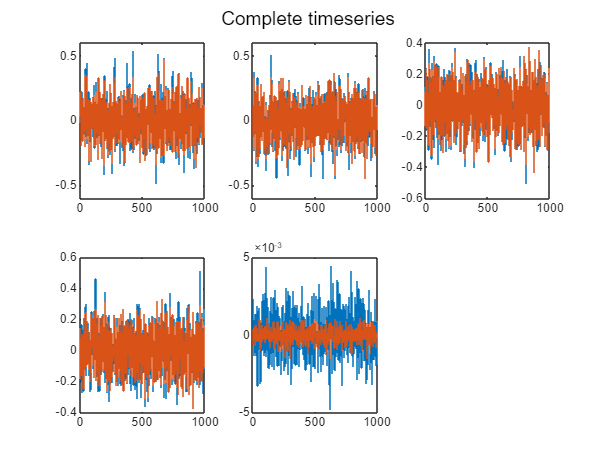

pred = extractdata(FFnet.predict(dlX));
figure
subplot(ceil(Noutputs/3), 3, 1)
stairs(1:Nsamples, Y(1, :))
hold on
stairs(1:Nsamples, pred(1, :))
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    stairs(1:Nsamples, Y(idx, :))
    hold on
    stairs(1:Nsamples, pred(idx, :))
    hold off
end
sgtitle('Complete timeseries');

## Error histogram

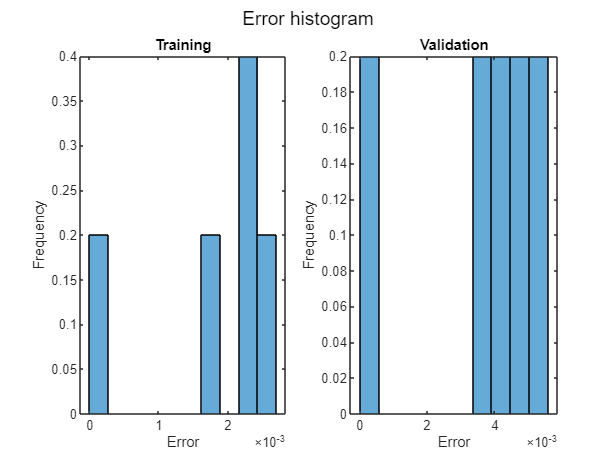

figure
subplot(1, 2, 1)
histogram(mean((Y_tr_pred - Y_tr).^2, 2), 10, 'Normalization', 'probability')
title("Training")
xlabel("Error");
ylabel("Frequency")

subplot(1, 2, 2)
histogram(mean((Y_val_pred - Y_val).^2, 2), 10, 'Normalization', 'probability')
title("Validation")
xlabel("Error");
ylabel("Frequency")

sgtitle('Error histogram');

## Regression

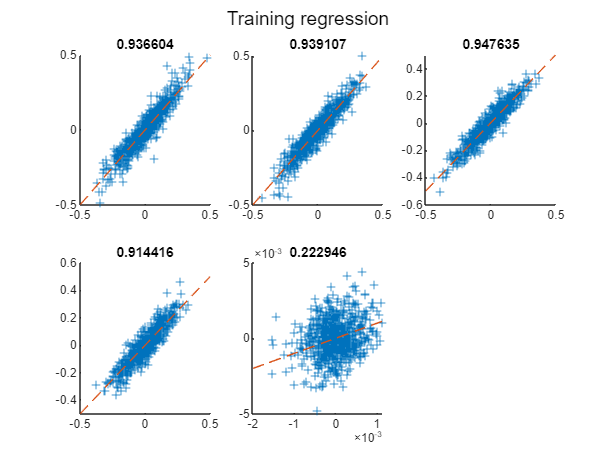

% xlabel("Predicted")
% ylabel("Actual")
% title("Correlation")

figure
title("Training")
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_tr_pred(1, :), Y_tr(1, :), "+")
title(corr(Y_tr_pred(1, :)', Y_tr(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_tr_pred(idx, :), Y_tr(idx, :), "+")
    title(corr(Y_tr_pred(idx, :)', Y_tr(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Training regression');

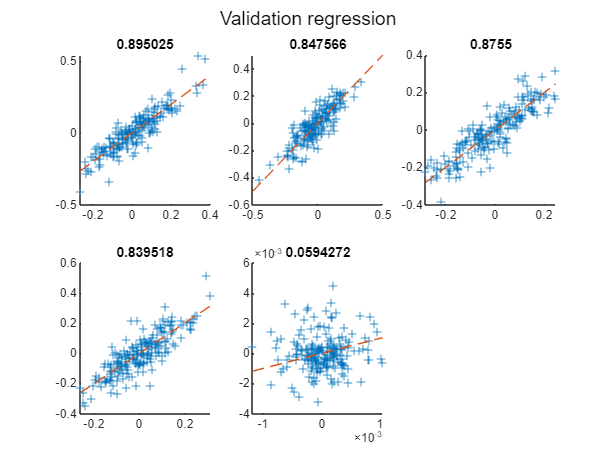


figure
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_val_pred(1, :), Y_val(1, :), "+")
title(corr(Y_val_pred(1, :)', Y_val(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_val_pred(idx, :), Y_val(idx, :), "+")
    title(corr(Y_val_pred(idx, :)', Y_val(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Validation regression');

## Weight matrix analysis

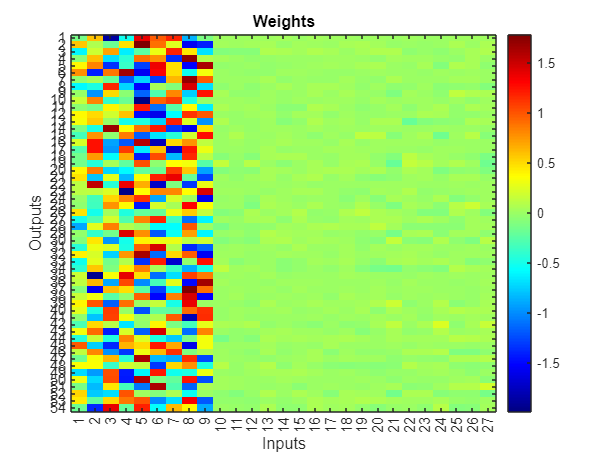

weights_input_hidden = FFnet.Learnables.Value;
weights_input_hidden = extractdata(weights_input_hidden{1});

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Weights');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));

Near zero weights

weights_treshold = 0.01 * max(abs(weights_input_hidden(:)))

weights_treshold = 0.0199

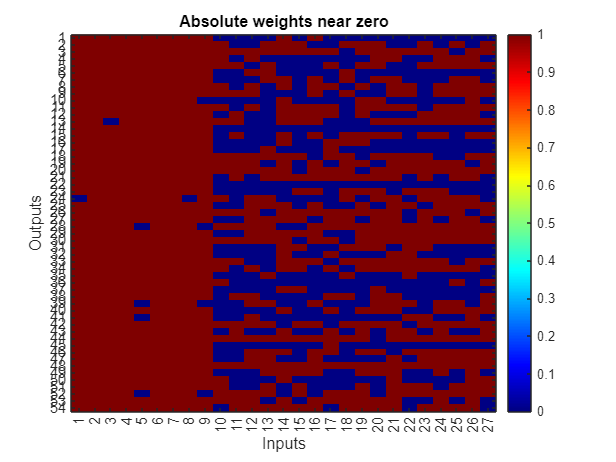

weights_input_hidden(abs(weights_input_hidden) <= weights_treshold) = 0;
weights_input_hidden(abs(weights_input_hidden) > weights_treshold) = 1;

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Absolute weights near zero');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));